# Results of AR modeling

names = {'AR(10)', 'svd', 'cpd_s', 'cpd_f', 'cpd_{cols}', 'cpd_{colf}', 'mlsvd'};

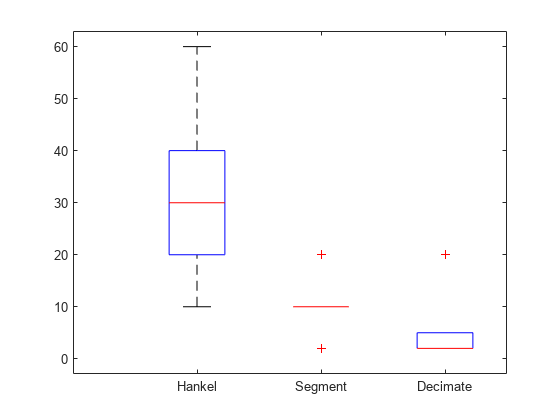

% Create a new figure
figure;
hold on;


% Prepare the data for boxplot
data = [best_dimensions_hankel(:, 1), best_dimensions_segment(:, 1), best_dimensions_decimate(:, 1)];
group = [ones(size(best_dimensions_hankel, 1), 1); 
         2 * ones(size(best_dimensions_segment, 1), 1); 
         3 * ones(size(best_dimensions_decimate, 1), 1)];

% Create the boxplot
boxplot(data(:), group, 'Labels', {'Hankel', 'Segment', 'Decimate'});

% Label the plot
xlabel('Method');
ylabel('L values');
title('Distribution of L values across different methods');



% Create a new figure
figure;
hold on;


% Prepare the data for boxplot
data = [best_dimensions_hankel(:, 2), best_dimensions_segment(:, 2), best_dimensions_decimate(:, 2)];
group = [ones(size(best_dimensions_hankel, 1), 1); 
         2 * ones(size(best_dimensions_segment, 1), 1); 
         3 * ones(size(best_dimensions_decimate, 1), 1)];

% Create the boxplot
boxplot(data(:), group, 'Labels', {'Hankel', 'Segment', 'Decimate'});

% Label the plot
xlabel('Method');
ylabel('M values');
title('Distribution of M values across different methods');

% Create a new figure
figure;
hold on;

new_fields = size(best_dimensions_hankel,1);

% Define a set of colors or markers for different fields
colors = lines(new_fields); % Using lines colormap for distinct colors
jitterAmount = 0.3;

% Prepare the data for boxplot
data = [best_comp_hankel(:, 1), best_comp_segment(:, 1), best_comp_decimate(:, 1)];
group = [ones(size(best_comp_hankel, 1), 1); 
         2 * ones(size(best_comp_segment, 1), 1); 
         3 * ones(size(best_comp_decimate, 1), 1)];

% Create the boxplot
boxplot(data(:), group, 'Labels', {'Hankel', 'Segment', 'Decimate'});

% Label the plot
xlabel('Method');
ylabel('R values');
title('Distribution of R component values across different methods');


% Create a new figure
figure;
hold on;

% Prepare the data for boxplot
data = [best_thresh_hankel(:, 1); best_thresh_segment(:, 1); best_thresh_decimate(:, 1)];
group = [ones(size(best_thresh_hankel, 1), 1); 
         2 * ones(size(best_thresh_segment, 1), 1); 
         3 * ones(size(best_thresh_decimate, 1), 1)];

% Create the boxplot
boxplot(data, group, 'Labels', {'Hankel', 'Segment', 'Decimate'});

% Calculate medians
medians = grpstats(data, group, 'median');

% Label the plot
xlabel('Method');
ylabel('Threshold values');
title('Distribution of threshold values across different methods');

% Add numbers next to the medians
positions = [1, 2, 3];
for i = 1:length(medians)
    text(positions(i), medians(i), sprintf('%.3f', medians(i)), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
end

% Adjust Y-axis limits to fully use the vertical axis
ylim auto; % Automatically set the limits based on the data

hold off;


% Prepare the data
rmseValues = zeros(8,7);
for i = 1:7
    rmseValues(:,i) = squeeze(ex9gt1mean(3,i+1,:));
end
rmseValuesNorm = rmseValues ./ max(rmseValues, [], 2);

% Create a new figure
figure;
hold on;

% Define colors and markers
colors = lines(7); % Use MATLAB's lines colormap
markers = {'o', 's', 'd', '^', 'v', '>', '<'};

% Plot each normalized RMSE
for i = 1:7
    plot(rmseValuesNorm(:,i), 'Color', colors(i,:), 'Marker', markers{i}, 'LineWidth', 1.5, 'DisplayName', names{i});
end

% Add grid, labels, and title
grid on;
legend(names, 'location', 'northeast');
xlabel('Parameter set');
ylabel('Normalized RMSE');
title('Normalized RMSE using 8 different signal parameters');

% Release the hold on the figure
hold off;

% Prepare the data
perfHankel = zeros(8,7);
perfSegment = zeros(8,7);
perfDecimate = zeros(8,7);
for i = 1:7
    perfHankel(:,i) = squeeze(ex9gt1mean(3,i+1,:));
    perfSegment(:,i) = squeeze(ex11gt1mean(3,i+1,:));
    perfDecimate(:,i) = squeeze(ex13gt1mean(3,i+1,:));
end

% Example data (replace with your actual data)
perfHankelMed = median(perfHankel, 1);
perfSegmentMed = median(perfSegment, 1);
perfDecimateMed = median(perfDecimate, 1);

% Combine the data into one matrix
sortedData = [perfHankelMed; perfSegmentMed; perfDecimateMed];

% Model names
modelNames = {'AR(10)', 'svd', 'cpd_s', 'cpd_f', 'cpd_{cols}', 'cpd_{colf}', 'mlsvd'};

% Create a new figure
figure;

% Plot the data as grouped bars
bar(sortedData);

% Set the legend and labels
legend(modelNames, 'Orientation', 'vertical', 'Location', 'eastoutside');
xticks([1 2 3]);
xticklabels({'Hankel', 'Segmented', 'Decimated'});
xlabel('Embeddings');
ylabel('RMSE');
title('RMSE of Models for Different Embeddings');
grid on;

ex9all = mean(ex9gt1mean,3)
ex11all = mean(ex11gt1mean,3)
ex13all = mean(ex13gt1mean,3)

ex18all = mean(ex18gt1mean,3)

figure;


plot(ex18all(:,1));
hold on;
plot(ex18all(:,2));
plot(ex18all(:,3));
plot(ex18all(:,4));

plot(ex18all(:,5));
plot(ex18all(:,6));
plot(ex18all(:,7));

hold off;

legend (names, 'location', 'northwest');
xlabel('Points forecasted ahead in time');
ylabel('RMSE');
title('RMSE values predicting trends over different parameter setups');